# 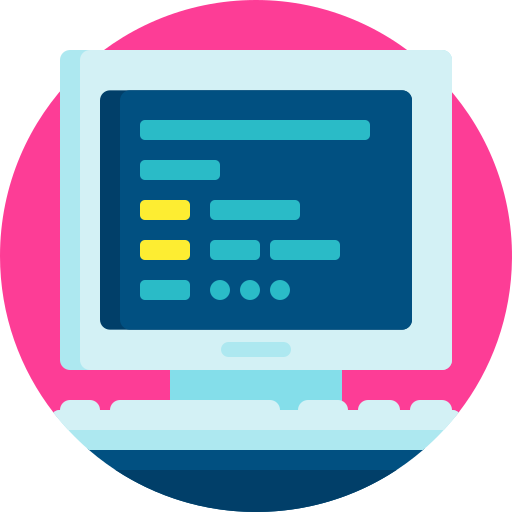

# Virtual Lab 5 - Forward kinematics of a 2R robot arm

#### This Virtual Lab covers Section 5.1-5.4 of the notes.

- This Virtual Lab will require both pen-on-paper work, as well as the use of MATLAB coding. The intention is to be able to solve the problems on paper (as you would in a Test/Exam) and then ratify the result using MATLAB.

- Make sure to save this file somewhere where you can access it again later, e.g. Google Drive/OneDrive/MATLAB Drive (or on your PC if you are working on a laptop). 

- This live script is intended to be used with the code shown. Select the `VIEW` tab and switch to `Output on right`.

- Each Section of this Live Script must be run individually. You can run Sections by using the `Run Section` button under the `LIVE EDITOR` ribbon (at the top of the screen), or using CNTL+ENTER (Windows) or CMD+ENTER (macOS).

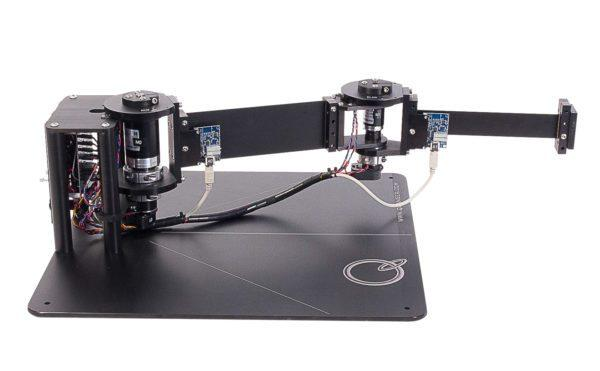

*2R planar manipulator from Quanser.*

This practical will introduce you to MATLAB's robotics toolbox by (digitally) constructing a 2R planar manipulator arm that can be used to test and visualise the robot's functionality (and verify our mathematical understanding of it).

We start by defining our robot as a [`rigidBodyTree`](https://www.mathworks.com/help/robotics/ref/rigidbodytree.html) (a connection of multiple rigid-body objects) using

robot = rigidBodyTree("DataFormat","column")

`rigidBodyTree` creates a default model that contains no rigid bodies. This object is initialised with a base coordinate frame that we will attach bodies to. You can think of this base as $\{W\}$. `robot `has a `base `object that we will later start attaching other rigid bodies to.

We can get additional detail on rigidBody by running 

help rigidBodyTree

It is highly advised that you use the `help `call when using a function for the first time to familiarise yourself with the various input/output arguments associated with a function, as well as the properties and related methods. Most help routines also provide a simple example of how to use the function and a link to the online documentation at the bottom.

We can create a rigid-body object using

manipulatorBase = rigidBody('manipulatorBase')

which defines a rigid body called `manipulatorBase`. A rigid body is the building block for any tree-structured robot manipulator. Each rigid body has a joint attached to it, which defaults to a fixed (static) joint. We can replace the fixed joint with a revolute (free to rotate) joint named `baseJoint`. We start by setting up the initial joint configuration

baseJoint = rigidBodyJoint('baseJoint','revolute');
baseJoint.JointAxis = [0 0 1];  %axis of rotation
baseJoint.HomePosition = 0; %initial angle of joint

p_baseJoint = [0, 0, 0];
tform = trvec2tform(p_baseJoint)
setFixedTransform(baseJoint,tform)

`rigidBodyJoint `defines baseJoint as a revolute (rotary) joint, the `HomePosition` object sets the orientation of `baseJoint` to 0 radians, and this orientation is defined about the joint axis of $[0~0~1]^T$ using the `JointAxis` object. We then define the location of `baseJoint`, which we place at $[0~0~0]^T$. Note that the function `trvec2tform` converts a translation vector into a transformation matrix, which is then used in `setFixedTransform` to define the full transformation matrix (it includes orientation information from *joint1)*.

The final step is to associate `baseJoint` to our rigid-body base, `manipulatorBase`

manipulatorBase.Joint = baseJoint

So we now have a joint that is located at $[0~0~0]^T$ on the rigid body `manipulatorBase`, with an axis of rotation set as $\hat{\bf z}_W=[0~0~1]^T$, which has an initial orientation of 0 radians. We can attach `manipulatorBase`, which is effectively just a joint, to the `base` of our robot reference frame.

addBody(robot,manipulatorBase,'base');

Note that when we link the `manipulatorBase` to `base` using `addBody`, our defined `baseJoint` pose will be relative to the `base` pose.

We can visualise our "robot", which is currently just a joint, using

fig = figure(1),clf;
show(robot,"Parent",axes(fig))
view(2)

Note that `view(2) `gives a direct view of the $\hat{\bf x}_W$-$\hat{\bf y}_W$ plane. In this 3D view we can see the reference frame attached to our joint, which we have located at the frame$\{W\}$ origin. You can rotate and zoom in/out using the plot tools as before to confirm.

** Question 1**: What is the rotation matrix that describes the current orientation of `baseJoint` with respect to the world frame?

%Answer block (if required)


We will now make our first manipulator link, which will also have a joint, `elbowJoint`, located at the one end of the link. We start with a similar setup process as previously:

link1 = rigidBody('link1');
elbowJoint = rigidBodyJoint('elbowJoint','revolute');

We will also define a nonzero *HomePosition angle of *$\pi/4$ about the default (joint axis) $$z-$axis$

elbowJoint.JointAxis = [0 0 1];
elbowJoint.HomePosition = pi/4;

This will define the orientation of the `elbowJoint` reference frame. 

We can also assign the location (although we technically have not attached the joint to anything yet) of `elbowJoint` using

p_elbowJoint = [.3, 0, 0];
tform2 = trvec2tform(p_elbowJoint);
setFixedTransform(elbowJoint,tform2);

We now associate `elbowJoint` with the `link1``.``Joint` object and attach the `link1` body to the `manipulatorBase` body (not the robot `base`)

link1.Joint = elbowJoint;
addBody(robot,link1,'manipulatorBase');

Once we add the `link1` rigid-body object to the `manipulatorBase`, we have defined the pose of the second joint's reference frame relative to the `link1` rigid body base (joint 1).

We can take another look at our robot configuration using `show()` as before.

fig = figure(1),clf;
show(robot,"Parent",axes(fig));
view(2)

** Question 2:** What is the distance between the two joints?

%Answer block (if required)


** Question 3: **What is the homogeneous transformation matrix of `elbowJoint` with respect to frame {W}?

%Answer block (if required)


We will now add our final link, following a similar process as before. The main difference is that instead of adding another revolute joint, we will add our static end-effector tool (i.e., we will not set the joint as revolute).

link2 = rigidBody('link2');
endEffectorJoint = rigidBodyJoint('endEffectorJoint');

Set the length of the second link to $l_2=0.3$m and add it to the `link1` body.

%Add code here


** Question 4:** What is the positional workspace of the end-effector in the world-frame x-y plane assuming no collisions are possible.

%Answer block (if required)


** Question 5:** What is the homogeneous transformation matrix describing the end effector pose with respect to the reference frame attached to `elbowJoint`?

%Answer block (if required)


** Question 6:** What is the homogeneous transformation matrix describing the end effector pose with respect to frame $\{W\}$?

%Answer block (if required)


** Question 7:** What is the pose vector in SE(2), $^W{\bf \xi}_B=[p_x~p_y~\psi]^T$, of the end-effector with respect to the world frame, where $^W{\bf p}=[p_x~p_y]^T$ is the world-frame description of the end-effector position, and $\psi$ is the orientation?

%Answer block (if required)


We can assign our joint home angles to variable `x0` using

x0=homeConfiguration(robot)

which will give the initialised joint angles for the two joints (packaged in a column vector). We can think of x`0` as our nominal configuration of joint angles that describes the configuration of the system.

** Question 8:** What dimension is the configuration space of our manipulator robot and why?

%Answer block (if required)


We can create another variable that will contain our joint configurations

x = zeros(2,1);

We will use this to adjust our robot configuration. Setting our current configuration as our home position

x = x0

we can access and adjust the first joint angle (for example) using x`(1).`

Set the first joint angle of $\bf x$ to $\pi/4$ in the code block below.

%Add code here


We can place our manipulator in this new configuration using 

fig = figure(1),clf;
show(robot,x,"Parent",axes(fig));
view(2)

Note that we have included `x` as a 2nd parameter in the function call `show`*, *which defines the configuration of the robot (it previously defaulted to the home positions).

** Question 9:** What is the new pose of the end-effector in SE(2) with respect to the world frame?

 %Answer block (if required)


** Question 10:** What value would $\bf x$ need to be in order for our end-effector position to be at (0,0.6)?

 %Answer block (if required)


** Question 11:** Given the configuration in **Question 10**, what would the end-effector orientation be?

 %Answer block (if required)


We can supply our robot with a trajectory in the configuration space and then animate the system to see how the robot behaviour evolves. We can start by defining a circular path for the first joint

s_path = linspace(0,2*pi,50);

This will create an array of 50 equally spaced elements, ranging from 0 to $2\pi$. We can then use a `for` loop to update our joint positions, show the robot visualisation, and then use `pause(0.05) `to update the figure every 0.05 seconds (you can change the pause time if you want to speed up or slow down the animation). 

x=x0; %sets the initial configuration equal to the home configuration
fig = figure(1),clf;
axis([-0.7 0.7 -0.7 0.7]) %sets axis limits

for s=s_path
    x(1) = x0(1)+s; %updates the baseJoint angle based on the new value of s
    
    show(robot,x,FastUpdate=1,PreservePlot=0);
    view(2)
    
    drawnow %forces matlab to plot immediately instead of after the loop finishes
    pause(.05)
end

We can compare our forward kinematic model of the `elbowJoint` position with the visualisation shown using the robotics toolbox by plotting the expected 2D position of `elbowJoint` based on forward kinematics.

x=x0;
fig = figure(1),clf;

hold on
axis([-0.7 0.7 -0.7 0.7]) 
plot(0.3*cos(s_path),0.3*sin(s_path),'k--') %forward kinematics of elbowJoint
for s=s_path
    x(1) = x0(1)+s;
    show(robot,x,'PreservePlot',false);
    view(2)       
    
    drawnow
    pause(0.05)
end

Copy the code from above and alter it in the code block below so that the end-effector path is *also* plotted using the same manoeuvre. Use two different plot colours to easily differentiate between the two paths.

%Add code here


** Question 12:** Include the additional line(s) of code as your answer to this question.

Copy the code from above and alter it in the code block below so that the end-effector maintains its initial orientation at all times while the `baseJoint` experiences a full 360 degree sweep using `s_path`. The `end-effector` and `baseJoint` path that is plotted using forward kinematics should match the motion of the simulation.

%Add code here


** Question 13:** Add the code above as your answer to this question.

** Question 14:** Upload your completed Virtual Lab .mlx file in Amathuba. Make sure to include your student number in the file name.